# Chapter 3

## Demand Modelling

- **How we can generate realistic demands**

- How to allocate demands in nodes using GIS

- Time series decomposition

- Function approximaiton for periodic signals

- Estimating the next demand

- Forecasting demands

Load library paths

start_toolkit

EPANET-MATLAB Toolkit Paths Loaded.


## Generating nodal demands using STREaM

The STochastic Residential water End-use Model (STREaM), is an open source simulation engine to generate realistic residential demands using a historical database of consumptions. More informaiton can be found here: [https://github.com/acominola/STREaM](https://github.com/acominola/STREaM)

Paper [https://www.sciencedirect.com/science/article/pii/S1364815217311301](https://www.sciencedirect.com/science/article/pii/S1364815217311301)

Using the following code, we can create the demands of a node of 1000 households

%% Select High Efficiency (HE) appliances
param.appliances.HEToilet = 1;
param.appliances.HEShower = 1;
param.appliances.HEFaucet = 1;
param.appliances.HEClothesWasher = 1;
param.appliances.HEDishwasher = 1;
param.appliances.HEBathtub = 1;

param.H = 1; % Simulation time in days
param.ts = 6; % Simulation time step: 1 minute = 6 * (Dt = 10 seconds)

load database.mat % Load database with patterns

Households = 1000; % Number of households to simulate

HouseDemands = zeros(24*param.H*60*6/param.ts, Households); % initialize

pop = 0;
for l = 1:Households
    rng(l); % Setting the seed for reproducibility
    param.HHsize = randomPopulation(1,1,[1 2 3 4 5 6; 0.267 0.603 0.761 0.898 0.961 1]); % Select 1-6 number of people in household in accordance to the US 2010 census.
    pop = pop + param.HHsize;
    %% Initialize simulation
    outputTrajectory = initializeTrajectories(param); 
    
    %% Generate water use time series
    outputTrajectory = generateConsumptionEvents(outputTrajectory, param, database); 
    
    %% Aggregate total water usage
    outputTrajectory = sumToTotal(outputTrajectory); 
   
    %% Scale data to desired 1-hour resolution
    outputTrajectory = aggregateSamplingResolution(outputTrajectory, param); 
    
    %% Save results
    HouseDemands(:,l) = outputTrajectory.TOTAL;
    if mod(l,10)==0
        fprintf('Simulated %d households\n', l);
    end
end

Simulated 10 households
Simulated 20 households
Simulated 30 households
Simulated 40 households
Simulated 50 households
Simulated 60 households
Simulated 70 households
Simulated 80 households
Simulated 90 households
Simulated 100 households
Simulated 110 households
Simulated 120 households
Simulated 130 households
Simulated 140 households
Simulated 150 households
Simulated 160 households
Simulated 170 households
Simulated 180 households
Simulated 190 households
Simulated 200 households
Simulated 210 households
Simulated 220 households
Simulated 230 households
Simulated 240 households
Simulated 250 households
Simulated 260 households
Simulated 270 households
Simulated 280 households
Simulated 290 households
Simulated 300 households
Simulated 310 households
Simulated 320 households
Simulated 330 households
Simulated 340 households
Simulated 350 households
Simulated 360 households
Simulated 370 households
Simulated 380 households
Simulated 390 households
Simulated 400 households
Simulated


average_demand = mean(sum(HouseDemands,2))

average_demand = 249.9095

depand_per_person = sum(sum(HouseDemands,2))/pop

depand_per_person = 146.4671

Plot results

figure
TimeSim = datetime(2021,1,1,0,0:(size(HouseDemands,1)-1),0)

TimeSim = 1×1440 datetime array
Columns 1 through 434

   01-Jan-2021 00:00:00   01-Jan-2021 00:01:00   01-Jan-2021 00:02:00   01-Jan-2021 00:03:00   01-Jan-2021 00:04:00   01-Jan-2021 00:05:00   01-Jan-2021 00:06:00   01-Jan-2021 00:07:00   01-Jan-2021 00:08:00   01-Jan-2021 00:09:00   01-Jan-2021 00:10:00   01-Jan-2021 00:11:00   01-Jan-2021 00:12:00   01-Jan-2021 00:13:00   01-Jan-2021 00:14:00   01-Jan-2021 00:15:00   01-Jan-2021 00:16:00   01-Jan-2021 00:17:00   01-Jan-2021 00:18:00   01-Jan-2021 00:19:00   01-Jan-2021 00:20:00   01-Jan-2021 00:21:00   01-Jan-2021 00:22:00   01-Jan-2021 00:23:00   01-Jan-2021 00:24:00   01-Jan-2021 00:25:00   01-Jan-2021 00:26:00   01-Jan-2021 00:27:00   01-Jan-2021 00:28:00   01-Jan-2021 00:29:00   01-Jan-2021 00:30:00   01-Jan-2021 00:31:00   01-Jan-2021 00:32:00   01-Jan-2021 00:33:00   01-Jan-2021 00:34:00   01-Jan-2021 00:35:00   01-Jan-2021 00:36:00   01-Jan-2021 00:37:00   01-Jan-2021 00:38:00   01-Jan-2021 00:39:00   01-Jan-2021 00:40:00  

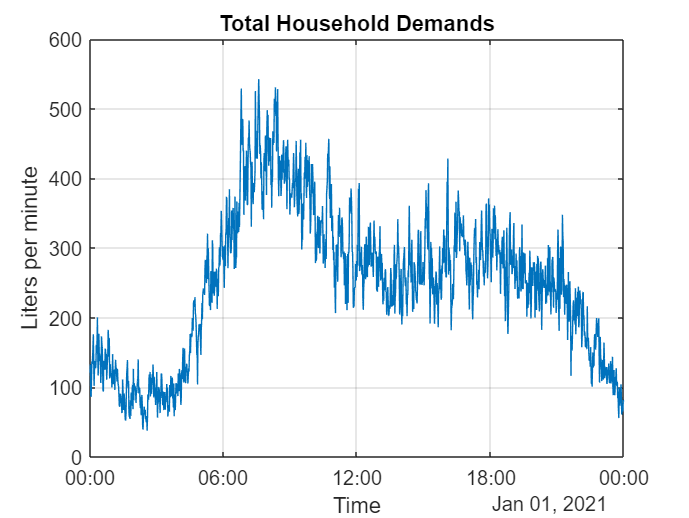

plot(TimeSim, sum(HouseDemands,2))
grid on
xlabel('Time')
ylabel('Liters per minute')
title('Total Household Demands')


houseID = 3;
figure
TimeSim = datetime(2021,1,1,0,0:(size(HouseDemands,1)-1),0)

TimeSim = 1×1440 datetime array
Columns 1 through 434

   01-Jan-2021 00:00:00   01-Jan-2021 00:01:00   01-Jan-2021 00:02:00   01-Jan-2021 00:03:00   01-Jan-2021 00:04:00   01-Jan-2021 00:05:00   01-Jan-2021 00:06:00   01-Jan-2021 00:07:00   01-Jan-2021 00:08:00   01-Jan-2021 00:09:00   01-Jan-2021 00:10:00   01-Jan-2021 00:11:00   01-Jan-2021 00:12:00   01-Jan-2021 00:13:00   01-Jan-2021 00:14:00   01-Jan-2021 00:15:00   01-Jan-2021 00:16:00   01-Jan-2021 00:17:00   01-Jan-2021 00:18:00   01-Jan-2021 00:19:00   01-Jan-2021 00:20:00   01-Jan-2021 00:21:00   01-Jan-2021 00:22:00   01-Jan-2021 00:23:00   01-Jan-2021 00:24:00   01-Jan-2021 00:25:00   01-Jan-2021 00:26:00   01-Jan-2021 00:27:00   01-Jan-2021 00:28:00   01-Jan-2021 00:29:00   01-Jan-2021 00:30:00   01-Jan-2021 00:31:00   01-Jan-2021 00:32:00   01-Jan-2021 00:33:00   01-Jan-2021 00:34:00   01-Jan-2021 00:35:00   01-Jan-2021 00:36:00   01-Jan-2021 00:37:00   01-Jan-2021 00:38:00   01-Jan-2021 00:39:00   01-Jan-2021 00:40:00  

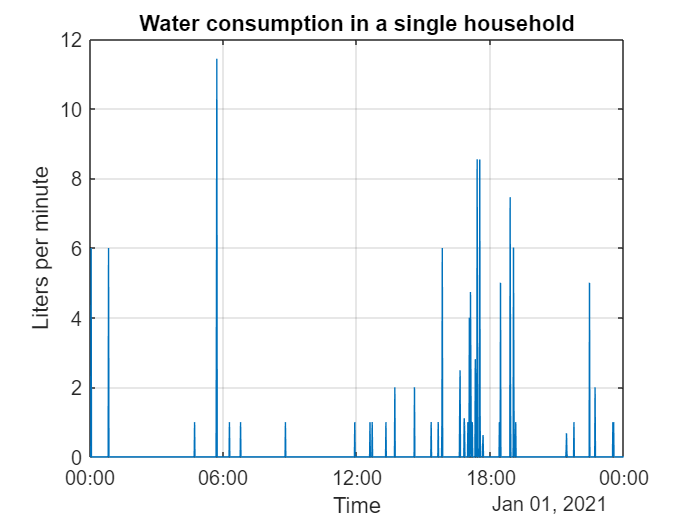

plot(TimeSim, HouseDemands(:,houseID))
grid on
xlabel('Time')
ylabel('Liters per minute')
title('Water consumption in a single household')

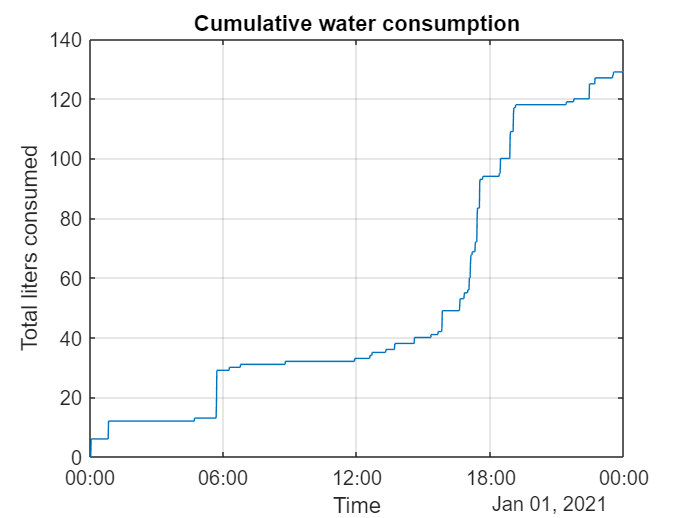


figure
plot(TimeSim, cumsum(HouseDemands(:,houseID)))
grid on
xlabel('Time')
ylabel('Total liters consumed')
title('Cumulative water consumption')

## Generating nodal demands using billing demands

Base demands are the average demand outflows supplied by a node. A node is a graph element, which we assume the water meters are connected with to provide water. A node also includes the unaccounted-for water.

The actual demands may fluctuate, depending on the demand patterns, however their average typically will converge towards the historical mean values. 

There are different ways of allocating demand:

- Top-down: Estimate total volume of residential use and compute demand per capita per time; given population density or number of houses and estimated number of people serving each node, compute demands.

- Bottom-up: use GIS information to assign customer to node, and correct for unaccounted-for water as demand = node-consumption x (produced/metered-sale)

**References:**

Walski Chapter 4 Water Consumption

[https://www.researchgate.net/profile/Vasilis-Kanakoudis/publication/259052233_Properly_allocating_the_urban_water_meter_readings_to_the_nodes_of_a_water_pipe_network_simulation_model/links/5c27664d299bf12be3a0d314/Properly-allocating-the-urban-water-meter-readings-to-the-nodes-of-a-water-pipe-network-simulation-model.pdf](https://www.researchgate.net/profile/Vasilis-Kanakoudis/publication/259052233_Properly_allocating_the_urban_water_meter_readings_to_the_nodes_of_a_water_pipe_network_simulation_model/links/5c27664d299bf12be3a0d314/Properly-allocating-the-urban-water-meter-readings-to-the-nodes-of-a-water-pipe-network-simulation-model.pdf)

[https://www.tandfonline.com/doi/pdf/10.1080/1573062X.2014.900811](https://www.tandfonline.com/doi/pdf/10.1080/1573062X.2014.900811)

Walski 2007 page pdf-181 http://docshare01.docshare.tips/files/12604/126049159.pdf

Davis  and  Brawn

rng(1)
G = epanet('smallnet4.inp');

EPANET version {20200} loaded (EMT version {dev2.2}).
Loading File "smallnet4.inp"...
Input File "smallnet4.inp" loaded sucessfuly.



figure
G.plot('nodes', 'yes', 'fontsize', 12, 'links', 'yes', 'fontsize', 12,'legendposition','SouthWest');
COORD = G.getNodeCoordinates;
x = COORD{1};
y = COORD{2};
voronoi(x,y)

axis equal
NCons = 300;
ConsX = randi(30,NCons,1)+25 + rand;
ConsY = randi(40,NCons,1)+35 + rand;

% based on the Household Size from US Census of 2010
population = randomPopulation(NCons,1,[1 2 3 4 5 6 7; 0.267 0.603 0.761 0.898 0.961 0.985 1])

population =      1
     1
     1
     5
     3
     2
     2
     4
     2
     5


averageConsumption = 150; % 150 litres per day per capita
dailyConsumerDemand = averageConsumption.*population

dailyConsumerDemand =    150
   150
   150
   750
   450
   300
   300
   600
   300
   750



%[V,C] = voronoin([x' y']);
plot(ConsX, ConsY, 'bo')

PQ = [ConsX, ConsY];
P = [x',y'];
[k, dist] = dsearchn(P,PQ)

k =      2
     3
     2
     4
     4
     4
     4
     2
     4
     3


dist =     8.8481
    6.5750
   11.6451
    6.4511
   14.8220
    9.8715
    6.0762
   12.2656
   11.7670
    7.7142


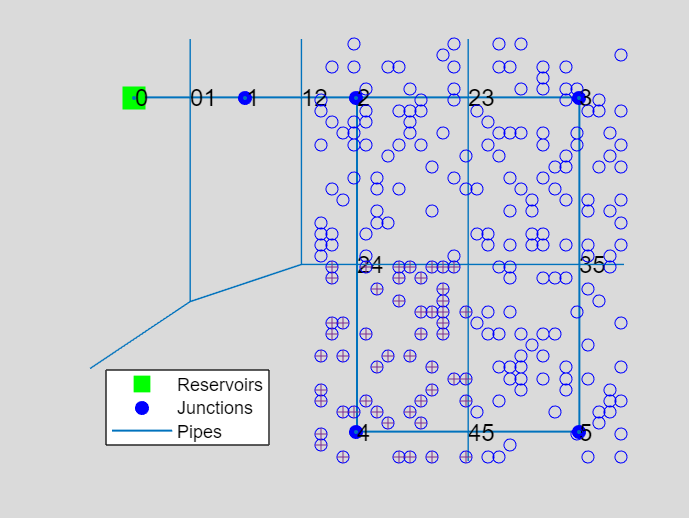


nodeid = 4;
plot(PQ(find(k==nodeid),1),PQ(find(k==nodeid),2),'+')


for i = 1:6
    l = find(k==i);
    node{i}.demand_cmd = sum(dailyConsumerDemand(l))/1000;
    node{i}.id = G.getNodeNameID(i);
end
%baseDemand
%G.getNodeNameID'
node{:}

ans = struct with fields:
    demand_cmd: 0
            id: {'1'}


ans = struct with fields:
    demand_cmd: 26.2500
            id: {'2'}


ans = struct with fields:
    demand_cmd: 27.6000
            id: {'3'}


ans = struct with fields:
    demand_cmd: 23.7000
            id: {'4'}


ans = struct with fields:
    demand_cmd: 35.7000
            id: {'5'}


ans = struct with fields:
    demand_cmd: 0
            id: {'0'}


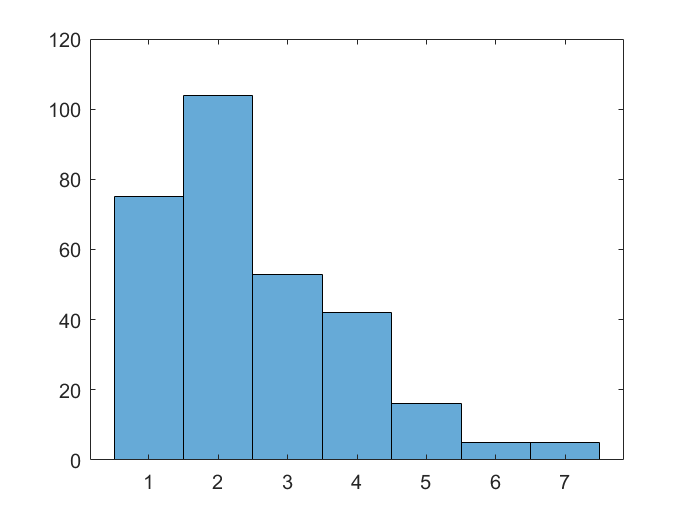


figure

histogram(population)



%hold on
%T = [];
%for i = 1:6
%    Polygon = V(C{i},:);
%    plot(Polygon(:,1), Polygon(:,2),'r-');
%    inpol = inpolygon(ConsX, ConsY, Polygon(:,1), Polygon(:,2));
%    plot(ConsX(inpol), ConsY(inpol), 'r.')
%end

rng(1) % Random seed 
%% Load a small network with 1 reservoir and 5 nodes
G = epanet('smallnet4.inp');

EPANET version {20200} loaded (EMT version {dev2.2}).
Loading File "smallnet4.inp"...
Input File "smallnet4.inp" loaded sucessfuly.


nCoord = G.getNodeCoordinates; 
x = nCoord{1};
y = nCoord{2};

%% Generate 300 consumer meters and allocate random demands
NCons = 300;
ConsX = randi(30,NCons,1)+25 + rand;
ConsY = randi(40,NCons,1)+35 + rand;
population = randomPopulation(NCons,1,[1 2 3 4 5 6 7; 0.267 0.603 0.761 0.898 0.961 0.985 1]); % generate random number of people serving each meter connection based on the US Sensus data of 2010. 
averageConsumption = 150; % 150 litres per day per capita
dailyConsumerDemand = averageConsumption.*population;
PQ = [ConsX, ConsY];
P = [x',y'];

%% Compute meters with the nearest distance from each node
[k, dist] = dsearchn(P,PQ);

for i = 1:6
    l = find(k==i);
    node{i}.demand_cmh = sum(dailyConsumerDemand(l))/1000/24; % compute the cubic meters per day
    node{i}.id = G.getNodeNameID(i); % node ID
end
node{:}

ans = struct with fields:
    demand_cmd: 0
            id: {'1'}
    demand_cmh: 0


ans = struct with fields:
    demand_cmd: 26.2500
            id: {'2'}
    demand_cmh: 1.0938


ans = struct with fields:
    demand_cmd: 27.6000
            id: {'3'}
    demand_cmh: 1.1500


ans = struct with fields:
    demand_cmd: 23.7000
            id: {'4'}
    demand_cmh: 0.9875


ans = struct with fields:
    demand_cmd: 35.7000
            id: {'5'}
    demand_cmh: 1.4875


ans = struct with fields:
    demand_cmd: 0
            id: {'0'}
    demand_cmh: 0


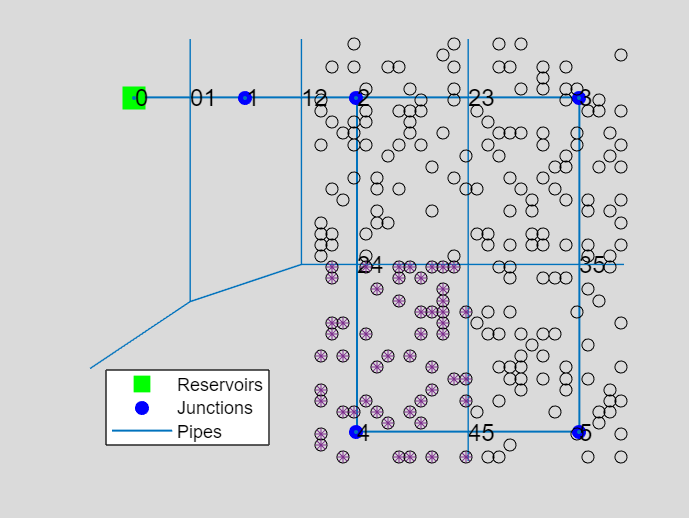


%% Plot the figure
figure;
G.plot('nodes', 'yes', 'fontsize', 12, 'links', 'yes', 'fontsize', 12,'legendposition','SouthWest');
voronoi(x,y) % compute the voronoi diagram
axis equal
plot(ConsX, ConsY, 'ko'); % plot the meters
% Meters which are linked to Node '4'
nodeid = 4;
plot(PQ(find(k==nodeid),1),PQ(find(k==nodeid),2),'*')

## Peak Factors

DMA inflows will be used for demonstrating how to create the peak factors

% import SCADA
load SCADA.mat

%how many days to plot
d = 1

d = 1

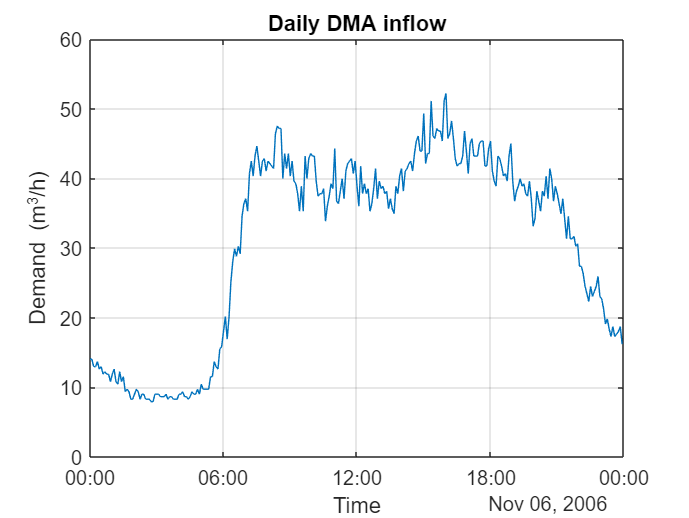

% compute time steps
D = 288*d;
f = Flow(1:D);

% plot DMA inflow
figure
plot(Tsim(1:D), f)
xlabel('Time')
ylabel('Demand (m^3/h)')
title('Daily DMA inflow')
grid on

**Calculation of peak factors **

d = 7

d = 7

% Get data for one week
D = 288*d;
f = Flow(1:D);
% create a matrix
f2 = reshape(f,288,d)

f2 =    14.0400   16.2000   17.2800   19.4400   16.2000   14.0400   18.0000
   14.0400   17.2800   18.0000   19.4400   14.7600   14.7600   15.8400
   12.9600   15.1200   17.2800   18.0000   16.5600   16.9200   15.4800
   12.9600   14.0400   16.9200   18.0000   16.2000   14.0400   17.2800
   13.6800   14.4000   16.2000   19.8000   14.7600   14.4000   15.1200
   12.6000   14.4000   15.1200   15.8400   16.2000   12.6000   13.6800
   12.9600   14.0400   14.4000   18.3600   17.2800   11.5200   15.4800
   11.8800   14.0400   13.6800   16.2000   15.1200   12.6000   14.4000
   12.2400   13.3200   12.2400   15.1200   14.4000   11.8800   12.9600
   11.8800   11.8800   12.2400   14.7600   14.7600   12.6000   14.4000


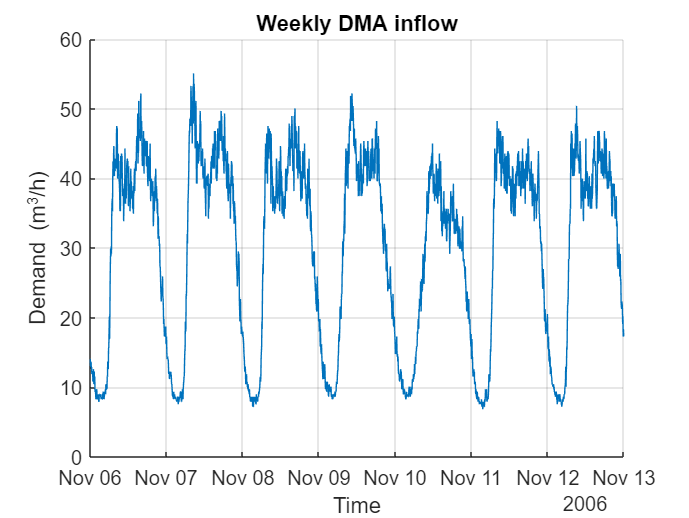


% plot DMA inflow
figure
hold on
plot(Tsim(1:288*d), f)
xlabel('Time')
ylabel('Demand (m^3/h)')
title('Weekly DMA inflow')
grid on

Compute peak factors as the mean consumption per hour, and per day. 

% mean value per 5 minutes
f2m = mean(f2,2)

f2m =    16.4571
   16.3029
   16.0457
   15.6343
   15.4800
   14.3486
   14.8629
   13.9886
   13.1657
   13.2171



% group per hour
f3 = reshape(f2m,12,24)

f3 =    16.4571   11.8800    9.7200    8.3829    8.2800    9.0000   15.5314   31.5771   41.0914   42.2743   42.0686   41.0400   41.0400   39.0857   39.3429   42.5314   42.4800   42.3257   43.0971   39.1371   36.4629   35.8457   27.5143   22.0629
   16.3029   12.0343    9.2057    8.4343    8.3829    9.2057   16.5600   32.7600   41.2457   41.9143   41.7600   40.1143   39.7543   39.1371   40.2686   41.1943   42.1200   41.6571   40.9886   37.8000   36.1543   36.6171   27.4114   21.4457
   16.0457   11.3143    9.5143    8.4857    8.3314    9.0000   16.6114   34.5086   38.9314   40.6800   42.2229   40.0629   40.6800   39.6000   40.9886   41.2971   41.2971   41.6057   41.6057   37.9543   34.3029   34.2514   26.7429   21.0857
   15.6343   11.3657    9.1029    8.5886    8.3314    9.1543   19.6457   37.2857   39.6000   41.4000   41.1943   39.7543   39.0857   37.3886   41.6057   40.6800   43.3029   41.8114   41.4514   38.7771   34.4057   35.2800   26.1257   20.6229
   15.4800   11.3143    9.4114 

f3m = mean(f3,1)

f3m =    14.5929   10.9671    9.0643    8.4471    8.6057   10.7314   22.7829   37.0671   41.6229   41.0314   41.5371   40.8086   38.8886   38.5200   41.5629   41.6957   42.3643   42.2400   40.8643   38.1771   36.1500   32.7557   25.9543   19.9671



% compute peak factors per hour
pfh = f3m/mean(f3m)

pfh =     0.4821    0.3624    0.2995    0.2791    0.2843    0.3546    0.7527    1.2247    1.3752    1.3557    1.3724    1.3483    1.2849    1.2727    1.3732    1.3776    1.3997    1.3956    1.3501    1.2614    1.1944    1.0822    0.8575    0.6597


% compute peak factors per day
pfd = mean(f2)/mean(mean(f2))

pfd =     1.0183    1.0709    1.0274    0.9985    0.8591    1.0033    1.0224


% make Monday the first day
pfd = [pfd(6:7), pfd(1:5)]

pfd =     1.0033    1.0224    1.0183    1.0709    1.0274    0.9985    0.8591


% example of peak factors per month (normalized with respect to montly consumption)
pfm = [0.8,0.9,1,1,1,1.1,1.2,1.2,1.1,0.9,0.9,0.9]

pfm =     0.8000    0.9000    1.0000    1.0000    1.0000    1.1000    1.2000    1.2000    1.1000    0.9000    0.9000    0.9000


mean(pfm)

ans = 1.0000

Plotting the peak factors (demand pattern)

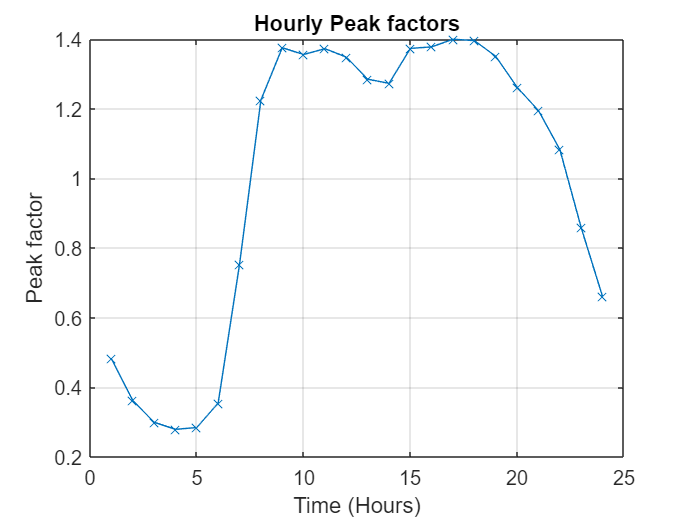

figure
plot(1:24, pfh, '-x')
xlabel('Time (Hours)')
ylabel('Peak factor')
title('Hourly Peak factors')
grid on

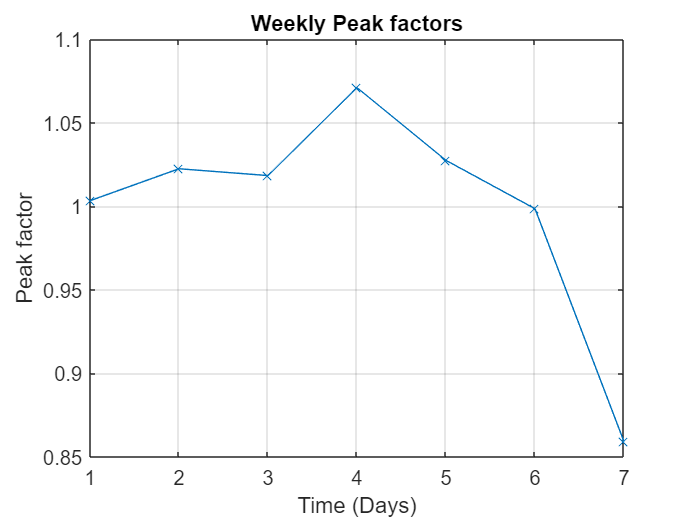


figure
plot(1:7, pfd, '-x')
xlabel('Time (Days)')
ylabel('Peak factor')
title('Weekly Peak factors')
grid on

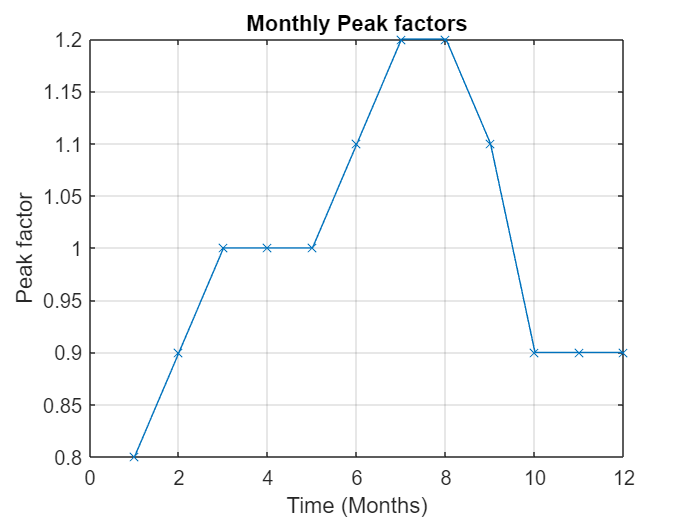


figure
plot(1:12, pfm, '-x')
xlabel('Time (Months)')
ylabel('Peak factor')
title('Monthly Peak factors')
grid on

**Therefore, we can generate the demand pattern for any date and time**

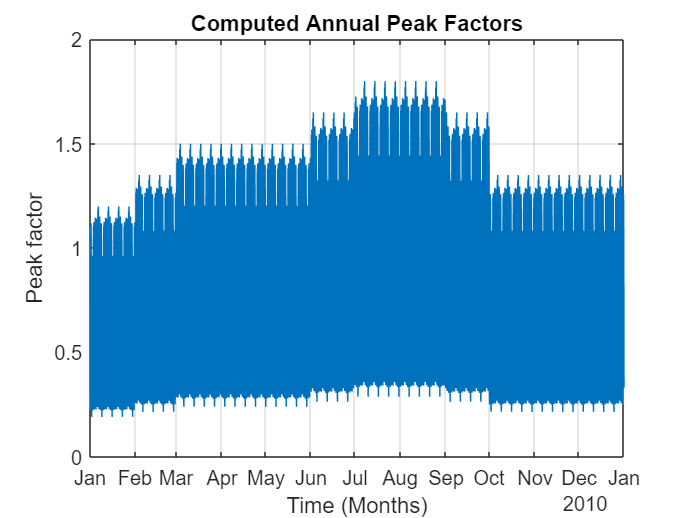

t = datetime(2021,01,01,0,0,0);
l = 1;
for d = 1:365
    for h = 1:24
        t = datetime(2010,1,1,l,0,0);
        pf(l) = pfm(t.Month)*pfd(weekday(t))*pfh(t.Hour+1);
        t2(l) = t;
        l = l + 1;
    end
end

figure
plot(t2,pf)
xlabel('Time (Months)')
ylabel('Peak factor')
title('Computed Annual Peak Factors')
grid on

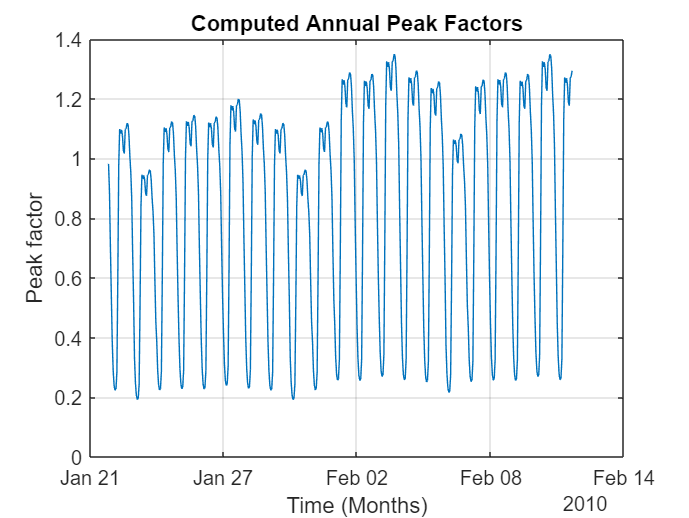



figure
plot(t2(500:1000),pf(500:1000))
xlabel('Time (Months)')
ylabel('Peak factor')
title('Computed Annual Peak Factors')
grid on

## Time Series decomposition

**Modelling water demands **

Water demands exhibit daily/weekly periodicy

We can learn this using various approximation functions, such as Fourier Series

%how many days to plot
d = 7

d = 7

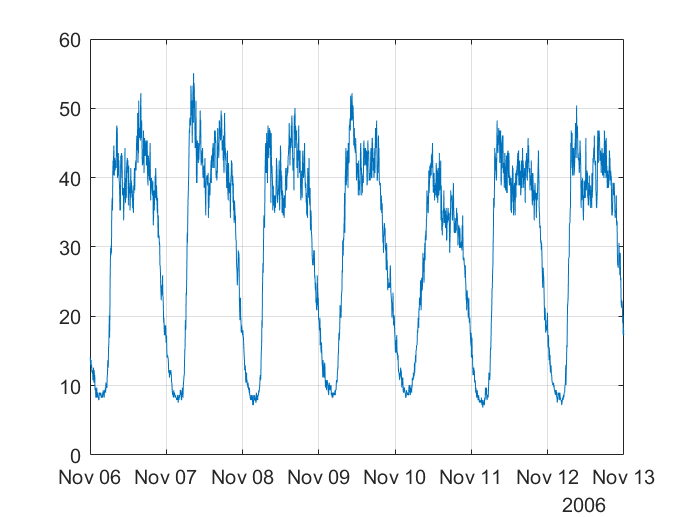

% compute time steps
D = 288*d;

KD = (1:D)';
TD = Tsim(KD);
FD = Flow(KD);

figure
plot(TD, FD)
grid on

We can approximate any continuous periodic signal using a combination of sines and cosines


$$y = a_0 + \sum_{i=1}^{n} a_i \cos(iwx) + b_i \sin(iwx)$$


How do we find the weights $a_0, a_i, b_i$? We can solve a "curve fitting" problem using least squares.

f = fit(KD,FD,'fourier8')

f =      General model Fourier8:
     f(x) = 
               a0 + a1*cos(x*w) + b1*sin(x*w) + 
               a2*cos(2*x*w) + b2*sin(2*x*w) + a3*cos(3*x*w) + b3*sin(3*x*w) + 
               a4*cos(4*x*w) + b4*sin(4*x*w) + a5*cos(5*x*w) + b5*sin(5*x*w) + 
               a6*cos(6*x*w) + b6*sin(6*x*w) + a7*cos(7*x*w) + b7*sin(7*x*w) + 
               a8*cos(8*x*w) + b8*sin(8*x*w)
     Coefficients (with 95% confidence bounds):
       a0 =       30.24  (30.07, 30.41)
       a1 =      -13.27  (-13.57, -12.98)
       b1 =      -9.854  (-10.17, -9.534)
       a2 =       -1.24  (-1.562, -0.9172)
       b2 =      -6.956  (-7.205, -6.706)
       a3 =       2.526  (2.277, 2.775)
       b3 =       1.014  (0.7501, 1.278)
       a4 =      -1.469  (-1.722, -1.217)
       b4 =       1.102  (0.8394, 1.365)
       a5 =      -1.185  (-1.432, -0.9382)
       b5 =     -0.5819  (-0.8437, -0.3201)
       a6 =      0.6263  (0.3766, 0.8759)
       b6 =     -0.6494  (-0.8979, -0.4009)
       a7 =      0.4464  (

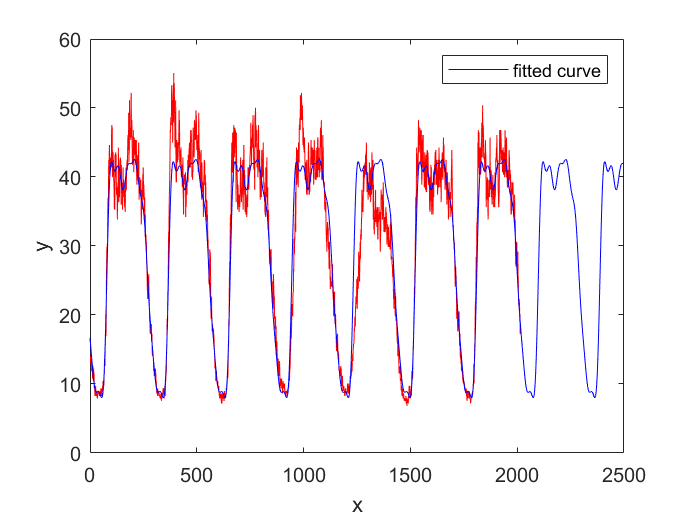

figure
plot(FD,'r')
hold all
plot(f,'b')

**Estimated periodicity**

per = 2 * pi / f.w % almost 288 = 5-minutes steps in 24 hours

per = 288.5858

**Improved model (daily pattern)**

coeffnames(f)

ans = 18×1 cell array
    {'a0'}
    {'a1'}
    {'b1'}
    {'a2'}
    {'b2'}
    {'a3'}
    {'b3'}
    {'a4'}
    {'b4'}
    {'a5'}
    {'b5'}
    {'a6'}
    {'b6'}
    {'a7'}
    {'b7'}
    {'a8'}
    {'b8'}
    {'w' }


coeffs = coeffvalues(f) 

coeffs =    30.2402  -13.2735   -9.8541   -1.2397   -6.9555    2.5259    1.0138   -1.4693    1.1021   -1.1851   -0.5819    0.6263   -0.6494    0.4464    0.9460   -0.0035   -0.0562    0.0218


coeffs(18) = 2 * pi /288

coeffs =    30.2402  -13.2735   -9.8541   -1.2397   -6.9555    2.5259    1.0138   -1.4693    1.1021   -1.1851   -0.5819    0.6263   -0.6494    0.4464    0.9460   -0.0035   -0.0562    0.0218


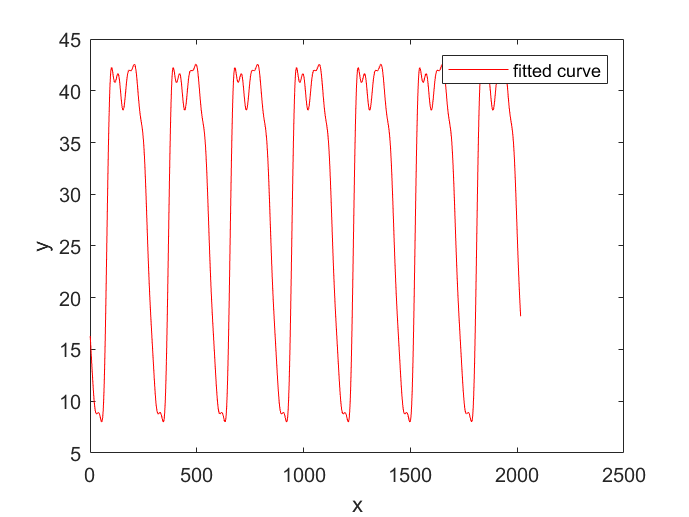

f2 = fit(KD,FD,'fourier8', 'StartPoint', coeffs);

figure
plot(f2)

### **Weekly periodicity**

%how many days to plot
dw = 7

dw = 7

% compute time steps
DW = 288*dw;

KDW = (1:DW)';
TDW = Tsim(KDW);
FDW = Flow(KDW);

ftmp = fit(KDW,FDW,'fourier8', 'StartPoint', coeffs);
perW = 2 * pi / ftmp.w /288 %in days, almost 7

perW = 1.0020


coeffs = coeffvalues(ftmp) 

coeffs =    30.2402  -13.2735   -9.8542   -1.2396   -6.9555    2.5259    1.0138   -1.4693    1.1021   -1.1851   -0.5819    0.6263   -0.6494    0.4463    0.9460   -0.0035   -0.0562    0.0218


coeffs(18) = 2 * pi /(288*7)

coeffs =    30.2402  -13.2735   -9.8542   -1.2396   -6.9555    2.5259    1.0138   -1.4693    1.1021   -1.1851   -0.5819    0.6263   -0.6494    0.4463    0.9460   -0.0035   -0.0562    0.0031


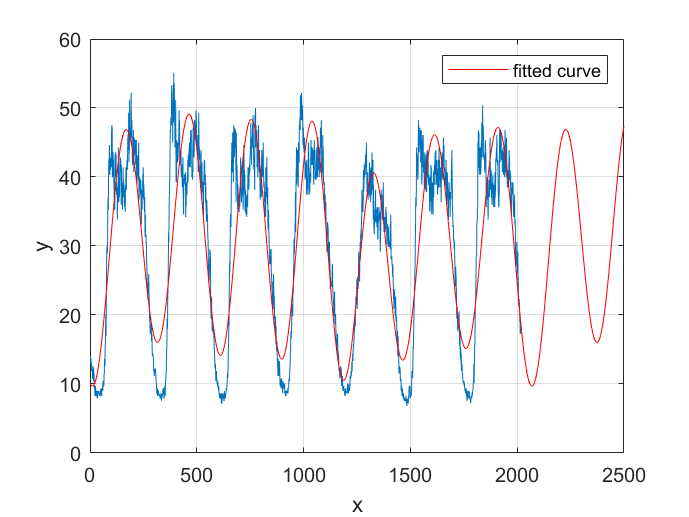

f3 = fit(KDW,FDW,'fourier8', 'StartPoint', coeffs);

figure
plot(FDW)
hold all
plot(f3)
grid on

### **Solving this for more Fourier coefficients**


$$y = a_0 + \sum_{i=1}^{n} a_i \cos(iwx) + b_i \sin(iwx)$$


load SCADA.mat % load SCADA dataset
FourierTerms = 50; % specify number of Fourier coefficients
dw = 21 % specify days for training

dw = 21

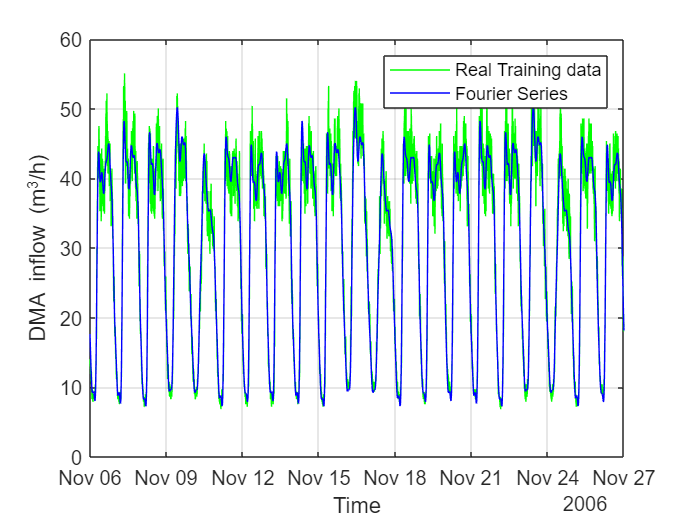

DW = 288*dw; % compute total time steps (5 minutes sampling time = 288 time steps)
KDW = (1:DW)'; TDW = Tsim(KDW); FDW = Flow(KDW);

%% Compute fundamental frequency 
w = 2 * pi/(288*7);

%% Create the Fourier parameter matrix
A = [ones(length(KDW),1) cos((1:FourierTerms)'*w*(KDW'))' sin((1:FourierTerms)'*w*(KDW'))'];

%% Solve using least squares the equations A*R = F
RCoef = A\FDW;

% Compute the Fourier Series
Ffs = A*RCoef;

figure
plot(TDW(KDW), FDW(KDW),'g')
hold on
plot(TDW(KDW), Ffs(KDW),'b')
grid on
legend('Real Training data','Fourier Series')
xlabel('Time')
ylabel('DMA inflow (m^3/h)')

### **Does this forecast the future?**

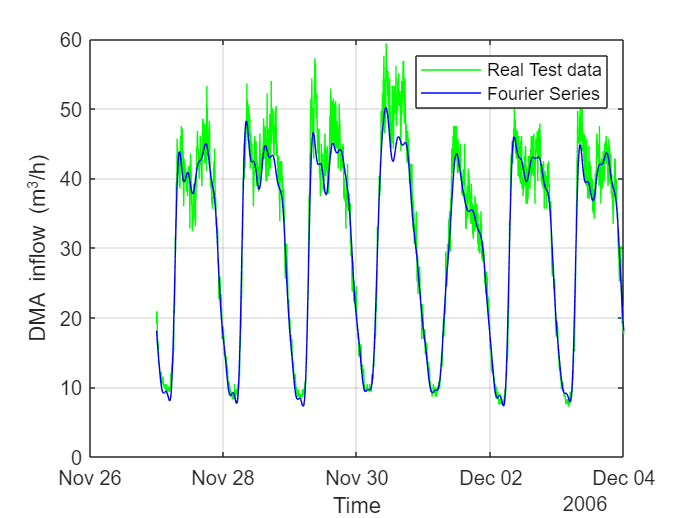

KDW = (DW:(DW+288*7))'; % next week, which we haven't learned

% compute the fourier values
A2 = [ones(length(KDW),1) cos((1:FourierTerms)'*w*(KDW'))' sin((1:FourierTerms)'*w*(KDW'))'];
% forecast 
f5 = A2*RCoef;

figure
plot(Tsim(KDW), Flow(KDW),'-g')
hold on
plot(Tsim(KDW), f5,'b')
grid on
legend('Real Test data','Fourier Series')
xlabel('Time')
ylabel('DMA inflow (m^3/h)')

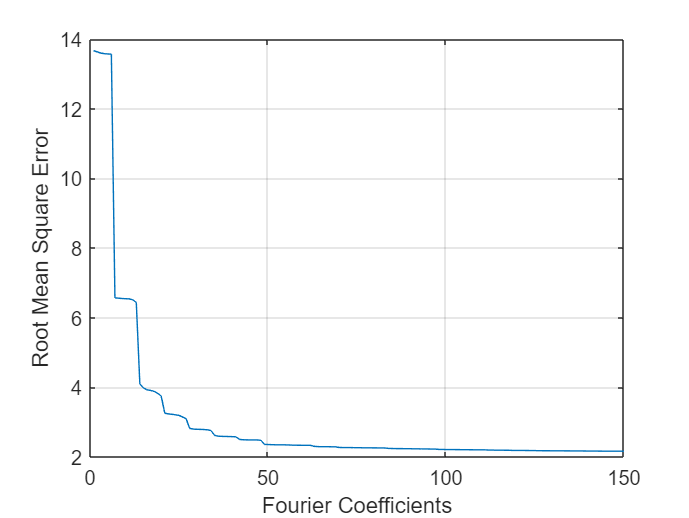

l = 1;
e = 0;
for i = 1 : 150
    FourierTerms = i; % specify number of Fourier coefficients
    dw = 21; % specify days for training
    DW = 288*dw; % compute total time steps (5 minutes sampling time = 288 time steps)
    KDW = (1:DW)'; TDW = Tsim(KDW); FDW = Flow(KDW);
    
    %% Compute fundamental frequency 
    w = 2 * pi/(288*7);
    
    %% Create the Fourier parameter matrix
    A = [ones(length(KDW),1) cos((1:FourierTerms)'*w*(KDW'))' sin((1:FourierTerms)'*w*(KDW'))'];
    
    %% Solve using least squares the equations A*R = F
    RCoef = A\FDW;
    
    % Compute the Fourier Series
    Ffs = A*RCoef;
    e(i) = rmse(FDW, Ffs);
    %li = l + 1;
end
figure
plot(e)
grid on
xlabel('Fourier Coefficients')
ylabel('Root Mean Square Error')

A different approach for demand modelling and forecasting, is using Holt Winters.

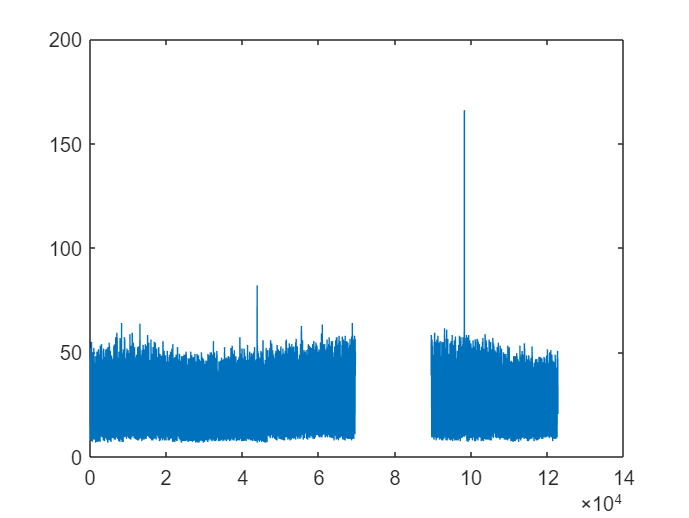

figure
plot(Flow)

figure
y = Flow(1:288*21);
L = 288*1;
m = 1

m = 1

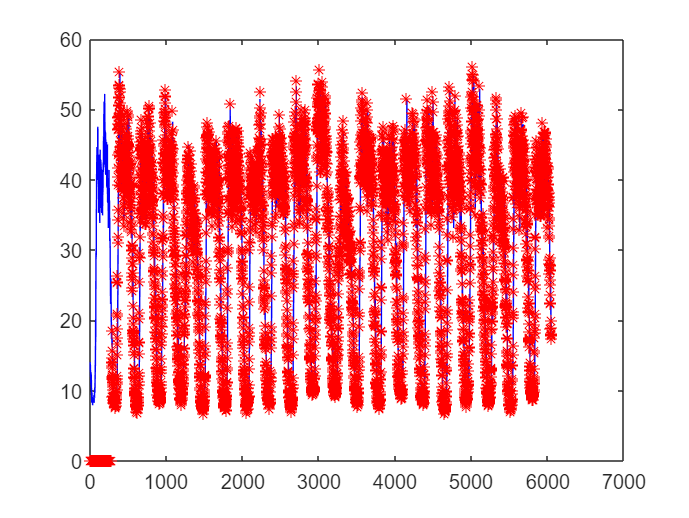

forecast for next value:18.008820


ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


holtwinters(y,L,m)

**Multiplicaltive model**


$$y(k) = r(k) s(k) (1+ \eta(k))$$


where

$r(k)$ is the annual seasonality 

$s(k)$ is the weekly periodicity

$\eta(k)$ is the noise, according to some distribution

Reconstructing the signal

**What is the distribution of the error?**

load SCADA.mat % load SCADA dataset
FourierTerms = 50; % specify number of Fourier coefficients
dw = 21 % specify days for training

dw = 21

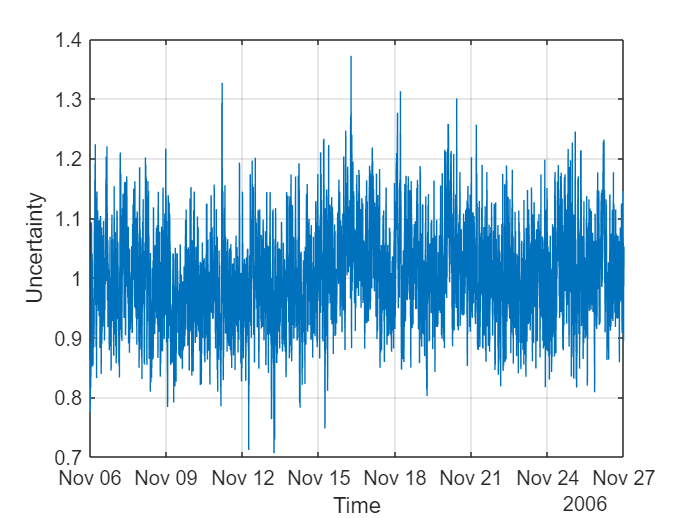

DW = 288*dw; % compute total time steps (5 minutes sampling time = 288 time steps)
KDW = (1:DW)'; TDW = Tsim(KDW); FDW = Flow(KDW);

%% Compute fundamental frequency 
w = 2 * pi/(288*7);

%% Create the Fourier parameter matrix
A = [ones(length(KDW),1) cos((1:FourierTerms)'*w*(KDW'))' sin((1:FourierTerms)'*w*(KDW'))'];

%% Solve using least squares the equations A*R = F
RCoef = A\FDW;

% Compute the Fourier Series
Ffs = A*RCoef;

eta = FDW./Ffs ;
figure
plot(TDW, eta)
grid on
xlabel('Time')
ylabel('Uncertainty')

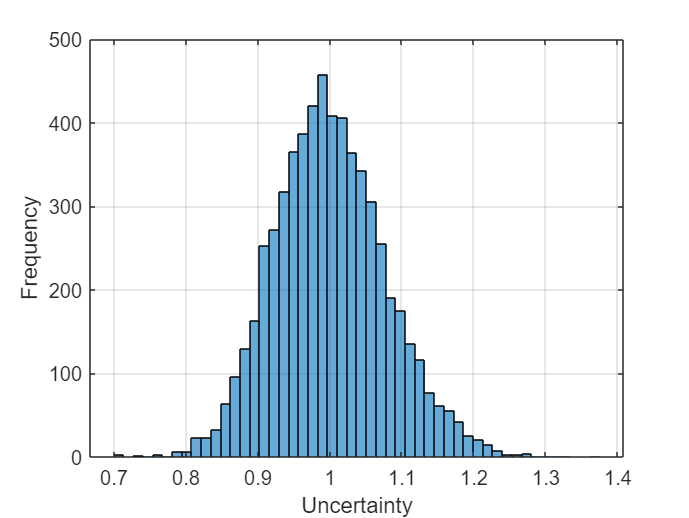


figure 
histogram(eta,50); 
xlabel('Uncertainty')
ylabel('Frequency')
grid on

### **Is it a Normal Distrbution?**

We can try a "normality test", such as the Lilliefors test, if h = 1 then reject the null hypothesis, i.e., not from a normal distribution.

[h1, p1] = lillietest(eta)

h1 = 1

p1 = 1.0000e-03

if h1 == 1
    disp('Not a normal distribution')
else
    disp('A normal distribution')
end

Not a normal distribution



kstest(eta)

ans = logical
   1



% [h2, p2] = lillietest(randn(100,1))
% if h2 == 1
%     disp('Not a normal distribution')
% else
%     disp('A normal distribution')
% end

Another way is to check the QQ plots

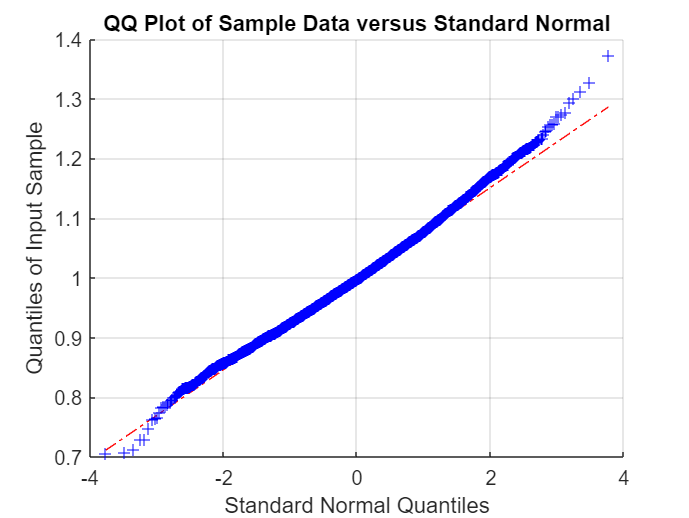

qqplot(eta) 
grid on

We observe that it does not fit the edges. 

Fit the logistic distribution to error

%pdlog = fitdist(eta,'Logistic')
%histfit(eta,50,'normal')
pdlog = fitdist(eta,'Lognormal')

pdlog =   LognormalDistribution

  Lognormal distribution
       mu = -0.00221448   [-0.0041727, -0.000256259]
    sigma =   0.0776842   [0.0763241, 0.079094]


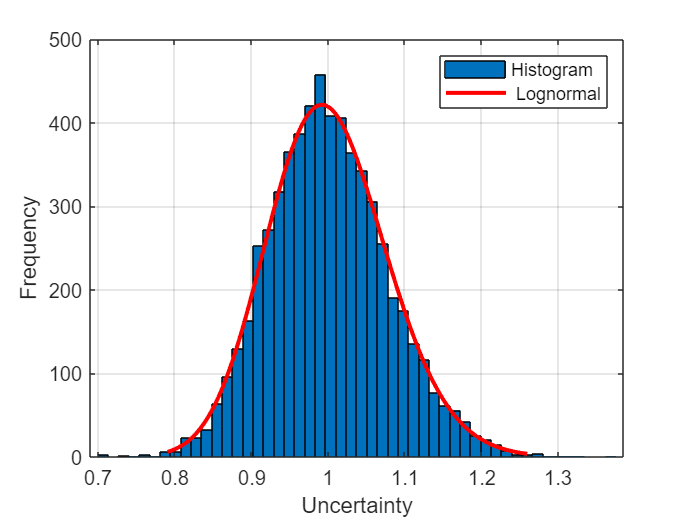

histfit(eta,50,'lognormal')
legend 'Histogram' ' Lognormal'
xlabel('Uncertainty')
ylabel('Frequency')
grid on

**Full demonstration of the decomposition**

T0 = 15063;
KDW = (1:T0)';
F = Flow(KDW);

% adjust for daylight saving ?
% 25 March 3->4 add 1 hour 0
% 28 March 4->3 delete first 3-4 

F(find(isnan(F)==1))=0; % remove nan

% trend

theta_t = [ones(T0,1) KDW]\F

theta_t =    30.4811
    0.0001


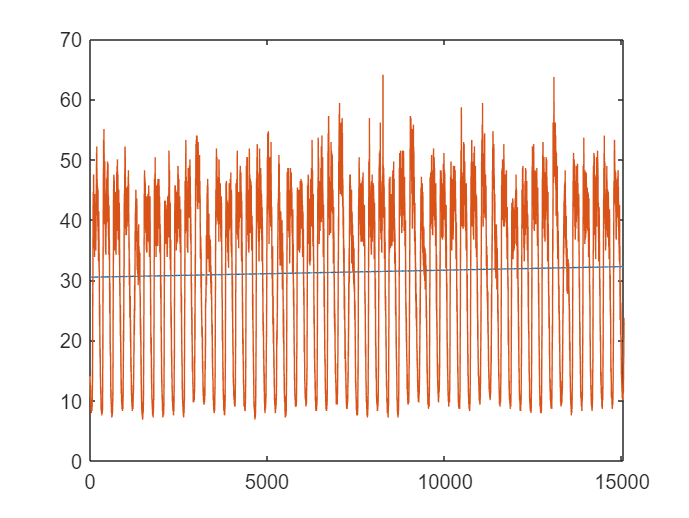


% remove trend
t = ([ones(T0,1) KDW]*theta_t);

figure
plot(t)
hold all
plot(F)


Fdt = F./t

Fdt =     0.4606
    0.4606
    0.4252
    0.4252
    0.4488
    0.4134
    0.4252
    0.3897
    0.4015
    0.3897


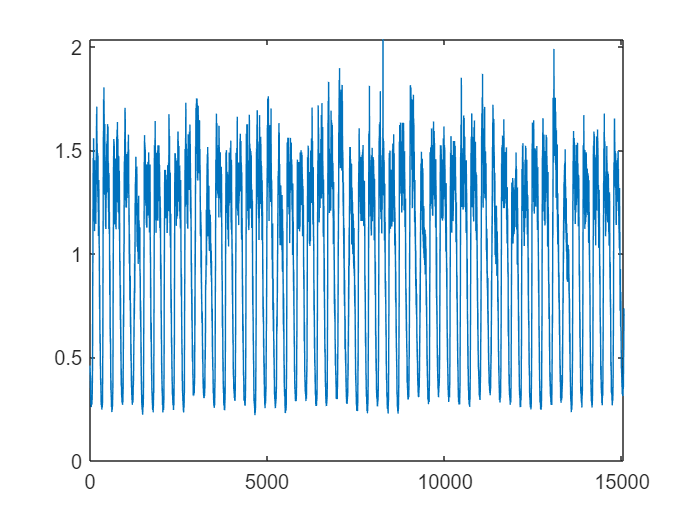


figure
plot(Fdt)

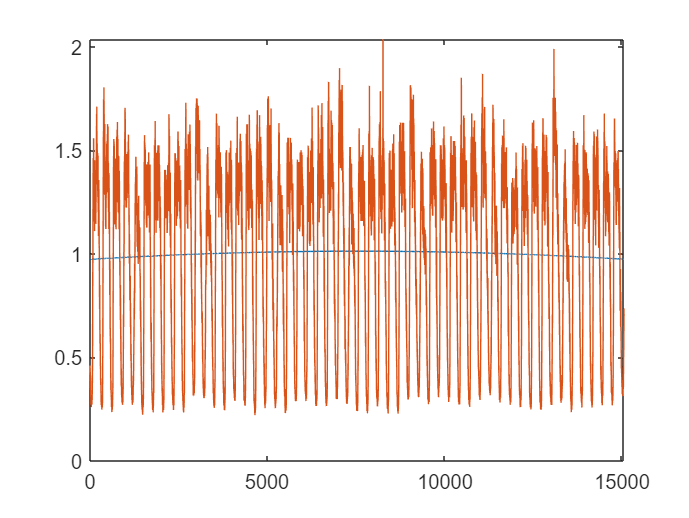


% seasonality
FourierTermsS = 1; % specify number of Fourier coefficients

%% Compute fundamental frequency 
wS = 2 * pi/(288*365);

%% Create the Fourier parameter matrix
AS = [ones(length(KDW),1) cos((1:FourierTermsS)'*wS*(KDW'))' sin((1:FourierTermsS)'*wS*(KDW'))'];

%% Solve using least squares the equations A*R = F
RCoefS = AS\Fdt;

% Compute the Fourier Series
s = AS*RCoefS;

figure

plot(s)
hold all
plot(Fdt)


Fdtds = F./t./s

Fdtds =     0.4731
    0.4731
    0.4367
    0.4367
    0.4609
    0.4245
    0.4366
    0.4002
    0.4124
    0.4002


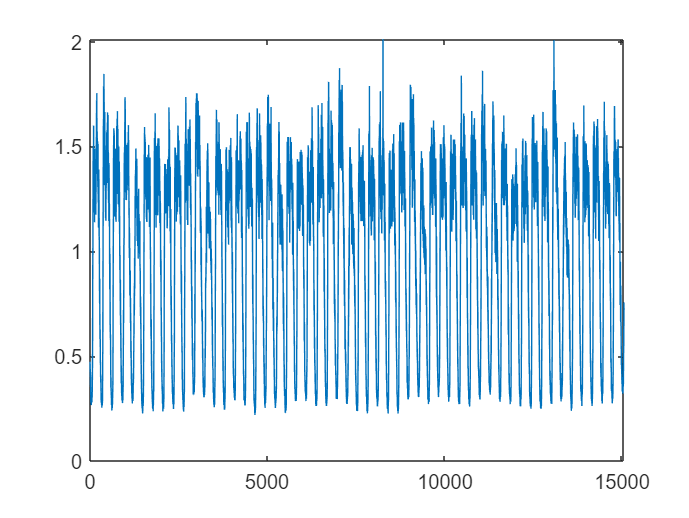


figure

plot(Fdtds)

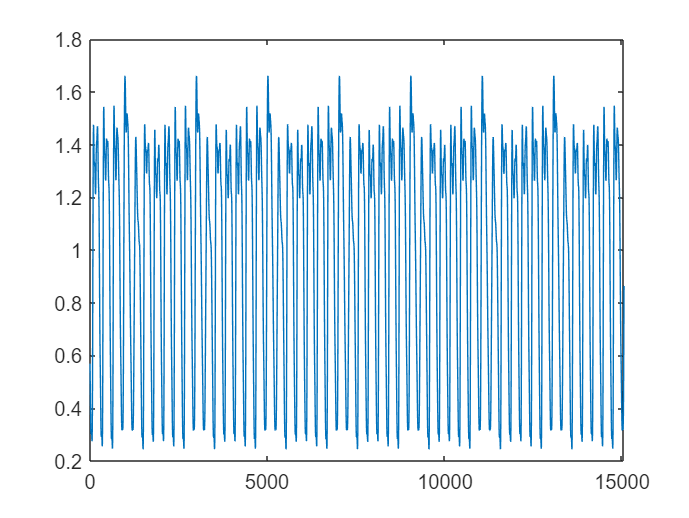



% seasonality
FourierTermsW = 50; % specify number of Fourier coefficients

%% Compute fundamental frequency 
wW = 2 * pi/(288*7);

%% Create the Fourier parameter matrix
AW = [ones(length(KDW),1) cos((1:FourierTermsW)'*wW*(KDW'))' sin((1:FourierTermsW)'*wW*(KDW'))'];

%% Solve using least squares the equations A*R = F
RCoefW = AW\Fdtds;

% Compute the Fourier Series
w = AW*RCoefW;


figure

plot(w)


Fdtdsdw = F./t./s./w

Fdtdsdw =     0.8317
    0.8505
    0.8028
    0.8210
    0.8866
    0.8357
    0.8800
    0.8263
    0.8726
    0.8685


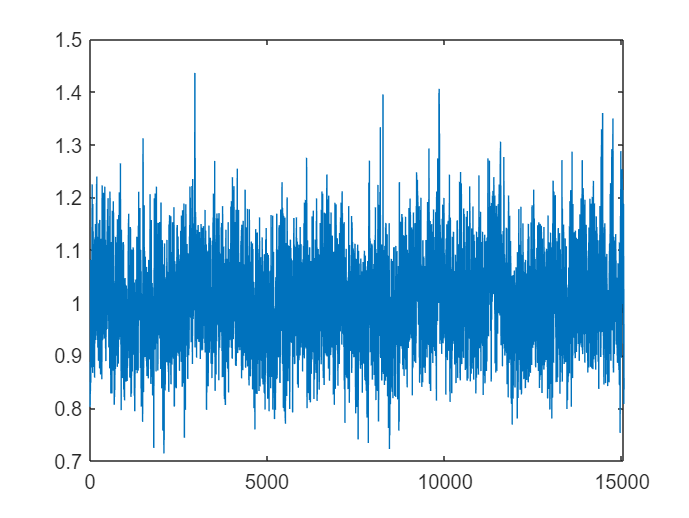


figure

plot(Fdtdsdw)

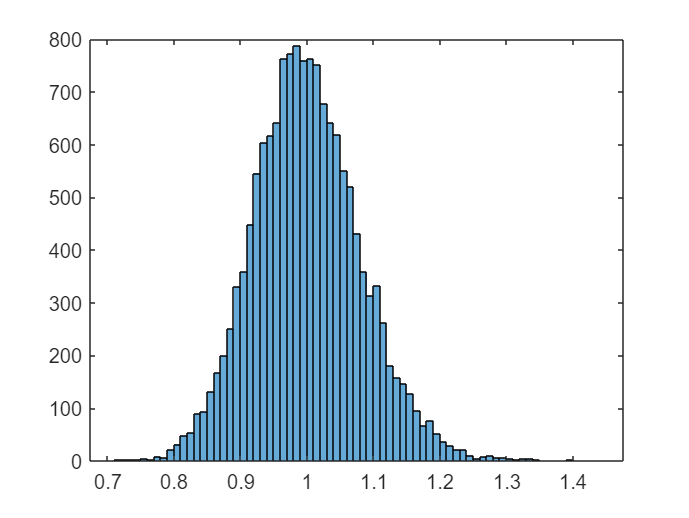


histogram(Fdtdsdw)

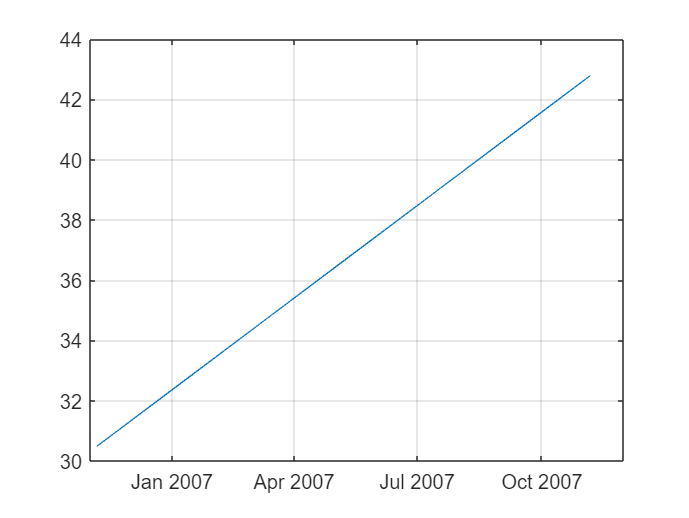


%% plot the decomposition
T0 = 288*365;
KDW = (1:T0)';
TDW = Tsim(KDW);

t = ([ones(T0,1) KDW]*theta_t);
figure
plot(TDW, t)
grid on

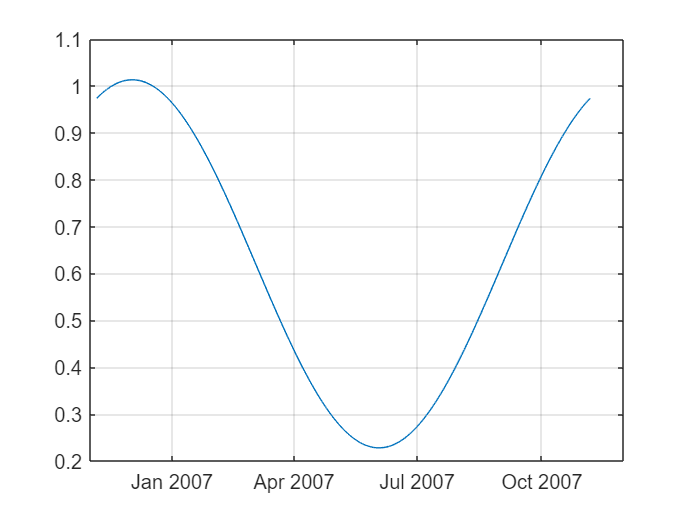



AS = [ones(length(KDW),1) cos((1:FourierTermsS)'*wS*(KDW'))' sin((1:FourierTermsS)'*wS*(KDW'))'];
s = AS*RCoefS;
figure
plot(TDW, s)
grid on

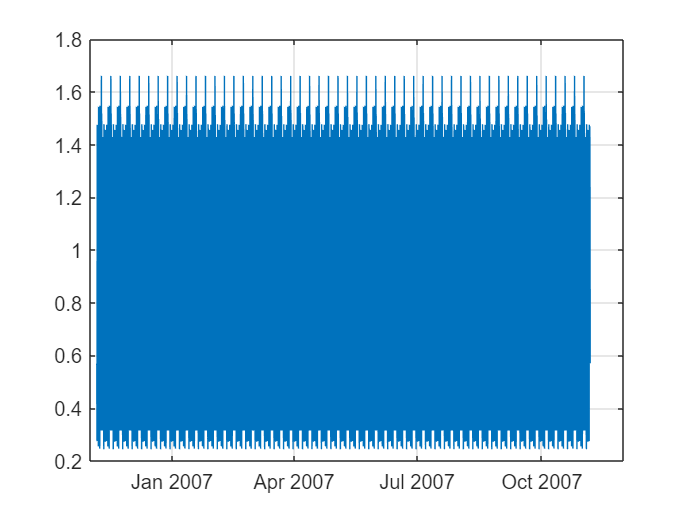


AW = [ones(length(KDW),1) cos((1:FourierTermsW)'*wW*(KDW'))' sin((1:FourierTermsW)'*wW*(KDW'))'];
w = AW*RCoefW;
figure
plot(TDW, w)
grid on

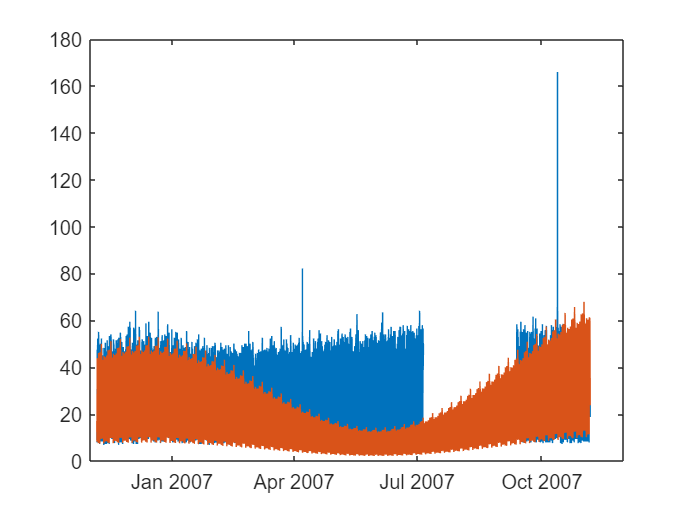


% put everything together

figure
plot(TDW, Flow(KDW))
hold all
plot(TDW, t.*s.*w)



%w = 2 * pi/(288*7);
%AW = [ones(length(KDW),1) cos((1:FourierTerms)'*w*(KDW'))' sin((1:FourierTerms)'*w*(KDW'))'];
%w = AW*RCoefW;


